# Experimental Fluids Lab #3

**Import and Initialize Pressure Vectors**

% C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab#3\Pressures
% Simply double click the file listed above

% Pressure data sampled at 800 Hz

% Wind off is from 0ms to ~187.5ms, or time = [1, 151]

% Steady State run time is from 400ms to 900 ms, or time = [321, 721]

% Time vector runs from 0 -> 2.5 sec over 2000 points

% Create Steady state pressure vectors

Pitot_SS = Pitot(321:721, 1);
Static3_SS = Static3(321:721, 1);
Static4_SS = Static4(321:721, 1);

Bias_pitot = mean(Pitot(1:151, 1)); % Pitot probe bias taken from wind-off (mBar)
Bias_stat3 = mean(Static3(1:151, 1)); % Static port #3 bias taken from wind-off (mBar)
Bias_stat4 = mean(Static4(1:151, 1)); % Static port #4 bias taken from wind-off (mBar)

P_o2 = (mean(Pitot_SS) - Bias_pitot) / 1000 % Pitot Probe mean pressure over steady state run time (Bar)

P_o2 = 1.8614

P_stat3 = (mean(Static3_SS) - Bias_stat3) / 1000; % Static port #3 mean pressure over steady state run time (Bar)
P_stat4 = (mean(Static4_SS) - Bias_stat4)/ 1000; % Static port #4 mean pressure over steady state run time (Bar)
P_stat = (P_stat3 + P_stat4) / 2 % Averaged Static Pressure (Bar)

P_stat = 0.3198

**Determine Incoming Flow Mach Number**

% Use the Rayleigh Pitot formula simplified for gamma = 1.4

P_o2_stat = P_o2 / P_stat

P_o2_stat = 5.8207

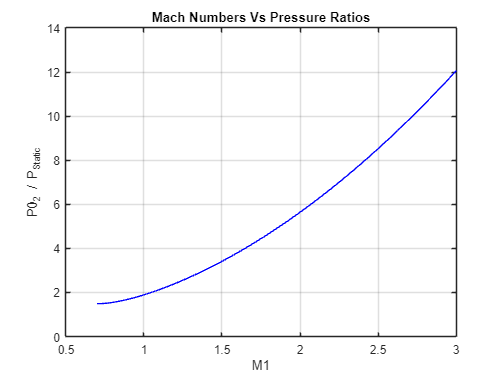


% (P_o2 / P1) = (6*M^2 / 5)^3.5 * (6 / (7*M^2 - 1))^2.5

% Define the range of M
M = 0.7:0.005:3;

% Calculate y (P_o2 / P1) for each possible value of M
y = (6*M.^2 / 5).^3.5 .* (6 ./ (7*M.^2 - 1)).^2.5;

% Plot the equation
plot(M, y, 'b-');
xlabel('M1');
ylabel('P0_2 / P_Static');
title('Mach Numbers Vs Pressure Ratios');
grid on;


M1 = M(268) % M(xxx) where xxx is the array index that matches closest to the calculated (P0_2 / P_Static)

M1 = 2.0350